Select a folder and calculate average Lab-value for each image.

**Do not run unless u want tro try another folder**

folder = "Images/flower"; % locate folder
name = 'labValuesFlowers.mat';
calculateLabValues(folder, name);
clear all;
% Estimated run time: 1 minute.

Load the image database and compute the color palette for each image

**Do not run unless u want tro try another folder**

% We should probably just calculate the most occuring color instead of
% color palettes.
imageFiles = dir('Images\flower\*.jpg');
nfiles = length(imageFiles);
numberOfColors = 10;
image_palettes = zeros(nfiles, numberOfColors, 3);
prog = 0;
tic
for i = 1:nfiles
    filename = fullfile(imageFiles(i).folder, imageFiles(i).name);
    I = imread(filename);
    I = im2double(I);
    imagePalette = calculateColorPalette(I, numberOfColors);
    image_palettes(i,:,:) = imagePalette;
    prog = ( 100*(i/nfiles) );
    fprintf(1,'\b\b\b\b%3.0f%%',prog); % Deleting 4 characters (The three digits and the % symbol)
end
toc
save('ImagePalettes.mat','image_palettes');
clear all
% Kmeans give lots of "Warning: failed to converge in 100 iterations.".
% Estimated run time: 22 minutes.

Select an image to reproduce and reproduce it!

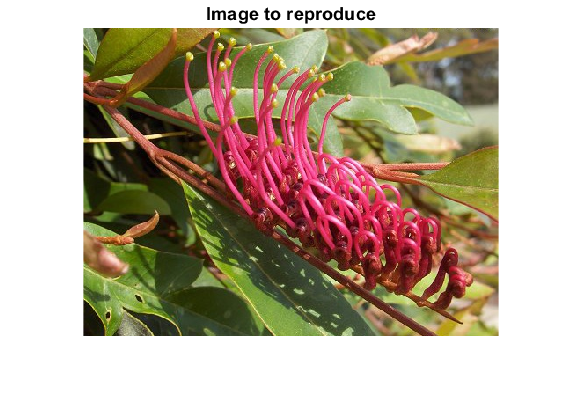

Elapsed time is 99.021095 seconds.


I = imread('Images\flower\flower_0009.jpg');
name = 'reproducedFlower_0009.jpg';
reproduceImage(I,name);

% Estimated run time: 99 seconds